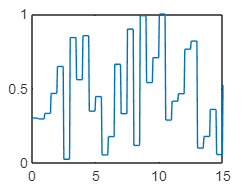

Ts = 0.05;
t_max = 15;
u = 0:Ts:t_max;
r = zeros(length(u),1);
Ts_beban = 0.5;
for k = 1:length(u)
    if mod(u(k),Ts_beban) == 0
        r(k) = rand(1);
    else
        r(k) = r(k-1);
    end
end
plot(u,r);